%% 데이터 불러오기
params_tbl = readtable('LHS 파라미터(csv).csv');

load('Vib_Data.mat');  % T_all 포함

% 입력 변수
X_all = [params_tbl.Spring, params_tbl.Comp_F, params_tbl.Reb_F, ...
         params_tbl.Comp_R, params_tbl.Reb_R];

% 출력 변수 (정규화)
normalize = @(x) (x - min(x)) / (max(x) - min(x));
roll_norm  = normalize(T_all.RollAngle_RMS_deg);
lat_norm   = normalize(T_all.RMS_LateralAcc_ms2);
pitch_norm = normalize(T_all.Pitch_Acc_RMS_degps2);
rolla_norm = normalize(T_all.Roll_Acc_RMS_degps2);
heave_norm = normalize(T_all.RMS_HeaveAcc_ms2);
psd_norm   = normalize(T_all.Heave_PSD_RMS_mps2);

% Score 정의
Handling_Score = 0.5 * (1 - roll_norm) + 0.5 * (1 - lat_norm);
Comfort_Score  = 0.3 * (1 - heave_norm) + 0.3 * (1 - psd_norm) + ...
                 0.2 * (1 - pitch_norm) + 0.2 * (1 - rolla_norm);

%% 학습/테스트 데이터 분리
N = size(X_all,1);
idx = randperm(N);
X_train = X_all(idx(1:16), :);
X_test  = X_all(idx(17:end), :);
H_train = Handling_Score(idx(1:16));
C_train = Comfort_Score(idx(1:16));
H_test  = Handling_Score(idx(17:end));
C_test  = Comfort_Score(idx(17:end));

%% GPR 모델 학습
gprModel_handling = fitrgp(X_train, H_train, 'KernelFunction','ardsquaredexponential','Standardize',true);
gprModel_comfort  = fitrgp(X_train, C_train, 'KernelFunction','ardsquaredexponential','Standardize',true);

%% 테스트 데이터 예측 정확도
H_pred_test = predict(gprModel_handling, X_test);
C_pred_test = predict(gprModel_comfort,  X_test);

rmse = @(y, yhat) sqrt(mean((y - yhat).^2));
fprintf('[테스트 예측 정확도]\n');

[테스트 예측 정확도]


fprintf('Handling RMSE: %.4f\n', rmse(H_test, H_pred_test));

Handling RMSE: 0.2640


fprintf('Comfort  RMSE: %.4f\n', rmse(C_test, C_pred_test));

Comfort  RMSE: 0.3739



%% Pareto 분석용 LHS 샘플링 (학습 데이터 범위 기반)
X_min = min(X_train);
X_max = max(X_train);

N_samples = 100000;
X_sampled = lhsdesign(N_samples, 5);
for j = 1:5
    X_sampled(:,j) = X_min(j) + (X_max(j) - X_min(j)) * X_sampled(:,j);
end

%% 예측 및 Pareto 계산
H_pred = predict(gprModel_handling, X_sampled);
C_pred = predict(gprModel_comfort,  X_sampled);

pareto_flags = paretofront([-H_pred, -C_pred]);

% 예측 분포 확인
fprintf('\n[예측값 분포 확인]\n');


[예측값 분포 확인]


fprintf('Handling Score: min %.4f | max %.4f | mean %.4f\n', ...
    min(H_pred), max(H_pred), mean(H_pred));

Handling Score: min 0.1605 | max 0.9738 | mean 0.4059


fprintf('Comfort  Score: min %.4f | max %.4f | mean %.4f\n', ...
    min(C_pred), max(C_pred), mean(C_pred));

Comfort  Score: min 0.0714 | max 1.0050 | mean 0.3883



%% Pareto 최적 해 시각화 및 출력
w_range = 0.1:0.1:0.9;
colors = jet(length(w_range));
legend_entries = {};

figure; hold on; grid on;
xlabel('Handling Score'); ylabel('Comfort Score');
title('Pareto Optimal Designs');
scatter(H_pred(pareto_flags), C_pred(pareto_flags), 20, [0.6 0.6 0.6], 'filled');

for i = 1:length(w_range)
    w_h = w_range(i);
    w_c = 1 - w_h;

    total_score = w_h * H_pred + w_c * C_pred;

    pareto_idx = find(pareto_flags);
    [~, best_local_idx] = max(total_score(pareto_idx));
    best_idx = pareto_idx(best_local_idx);

    % 최적점 출력
    fprintf('\n== Pareto 기반 최적 설계 (w_h: %.1f, w_c: %.1f) ==\n', w_h, w_c);
    fprintf('Spring   = %.2f\n', X_sampled(best_idx,1));
    fprintf('Comp_F   = %.2f\n', X_sampled(best_idx,2));
    fprintf('Reb_F    = %.2f\n', X_sampled(best_idx,3));
    fprintf('Comp_R   = %.2f\n', X_sampled(best_idx,4));
    fprintf('Reb_R    = %.2f\n', X_sampled(best_idx,5));
    fprintf('Handling Score = %.4f\n', H_pred(best_idx));
    fprintf('Comfort Score  = %.4f\n', C_pred(best_idx));
    fprintf('Total Score    = %.4f\n', total_score(best_idx));

    % 시각화
    scatter(H_pred(best_idx), C_pred(best_idx), 60, colors(i,:), 'filled');
    legend_entries{end+1} = sprintf('w_h: %.1f, w_c: %.1f', w_h, w_c);
end


== Pareto 기반 최적 설계 (w_h: 0.1, w_c: 0.9) ==


Spring   = 3.99


Comp_F   = 3.46


Reb_F    = 6.15


Comp_R   = 11.55


Reb_R    = 9.66


Handling Score = 0.9351


Comfort Score  = 1.0042


Total Score    = 0.9973



== Pareto 기반 최적 설계 (w_h: 0.2, w_c: 0.8) ==


Spring   = 3.99


Comp_F   = 3.46


Reb_F    = 6.15


Comp_R   = 11.55


Reb_R    = 9.66


Handling Score = 0.9351


Comfort Score  = 1.0042


Total Score    = 0.9904



== Pareto 기반 최적 설계 (w_h: 0.3, w_c: 0.7) ==


Spring   = 3.99


Comp_F   = 3.46


Reb_F    = 6.15


Comp_R   = 11.55


Reb_R    = 9.66


Handling Score = 0.9351


Comfort Score  = 1.0042


Total Score    = 0.9835



== Pareto 기반 최적 설계 (w_h: 0.4, w_c: 0.6) ==


Spring   = 3.97


Comp_F   = 10.32


Reb_F    = 5.93


Comp_R   = 10.79


Reb_R    = 9.43


Handling Score = 0.9417


Comfort Score  = 0.9999


Total Score    = 0.9766



== Pareto 기반 최적 설계 (w_h: 0.5, w_c: 0.5) ==


Spring   = 3.97


Comp_F   = 10.32


Reb_F    = 5.93


Comp_R   = 10.79


Reb_R    = 9.43


Handling Score = 0.9417


Comfort Score  = 0.9999


Total Score    = 0.9708



== Pareto 기반 최적 설계 (w_h: 0.6, w_c: 0.4) ==


Spring   = 3.99


Comp_F   = 3.52


Reb_F    = 5.12


Comp_R   = 10.47


Reb_R    = 9.60


Handling Score = 0.9645


Comfort Score  = 0.9733


Total Score    = 0.9680



== Pareto 기반 최적 설계 (w_h: 0.7, w_c: 0.3) ==


Spring   = 3.99


Comp_F   = 3.52


Reb_F    = 5.12


Comp_R   = 10.47


Reb_R    = 9.60


Handling Score = 0.9645


Comfort Score  = 0.9733


Total Score    = 0.9671



== Pareto 기반 최적 설계 (w_h: 0.8, w_c: 0.2) ==


Spring   = 3.99


Comp_F   = 10.07


Reb_F    = 4.84


Comp_R   = 10.03


Reb_R    = 9.66


Handling Score = 0.9690


Comfort Score  = 0.9577


Total Score    = 0.9668



== Pareto 기반 최적 설계 (w_h: 0.9, w_c: 0.1) ==


Spring   = 3.99


Comp_F   = 3.05


Reb_F    = 4.31


Comp_R   = 8.75


Reb_R    = 9.97


Handling Score = 0.9736


Comfort Score  = 0.9169


Total Score    = 0.9680


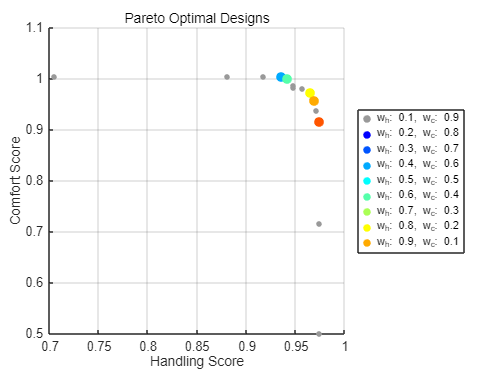


legend(legend_entries, 'Location', 'eastoutside');